# Converter Radar Data BGT60 and Bio Signal data

clc
clear all
close all

## Setup Data

Add necessary Library

addpath(".library\npy-matlab-master\npy-matlab\")
addpath("Heartsound_Analysis")


Select Dataset

anal_name = "mat_test";
% H:\Zharfan_Document\Project\AllReiProject\convert_radar_bgt60\.dataset\Data 22-25\Data25\BGT60TR13C_record_2504202420240425-132210\RadarIfxAvian_00
datasetnya = readNPY(".dataset\Data 22-25\Measurement 25042024\BGT60TR13C_record_2504202420240425-101640\RadarIfxAvian_00\radar.npy");
conf_fname =         '.dataset\Data 22-25\Measurement 25042024\BGT60TR13C_record_2504202420240425-101640\RadarIfxAvian_00\config.json'; 
biodata_file =       '.dataset\Radar_60Ghz_data\Normal\Different Condition\HS,ECG,PPG\Cough\C3.txt';


### Setup Radar BGT60TR13C

conf_fid = fopen(conf_fname); 
conf_raw = fread(conf_fid,inf); 
conf_str = char(conf_raw'); 
fclose(conf_fid); 
conf_confignya = jsondecode(conf_str);

fprintf("Chirps Reptition Time(s): %d", conf_confignya.device_config.fmcw_single_shape.chirp_repetition_time_s)

Chirps Reptition Time(s): 5.911250e-04

fprintf("num_chirps_per_frame: %i", conf_confignya.device_config.fmcw_single_shape.num_chirps_per_frame)

num_chirps_per_frame: 64

fprintf("num_samples_per_chirp: %i", conf_confignya.device_config.fmcw_single_shape.num_samples_per_chirp)

num_samples_per_chirp: 64

fprintf("sample_rate_Hz: %i", conf_confignya.device_config.fmcw_single_shape.sample_rate_Hz)

sample_rate_Hz: 2000000

fprintf("Frame Rate(Hz): %i", 1 / conf_confignya.device_config.fmcw_single_shape.frame_repetition_time_s)

Frame Rate(Hz): 1.294183e+01

Set Radar Parameter

Radar_Parameter.Num_Tx_Antennas = conf_confignya.device_config.fmcw_single_shape.tx_antennas

Radar_Parameter = struct with fields:
    Num_Tx_Antennas: 1


Radar_Parameter.Num_Rx_Antennas= length(conf_confignya.device_config.fmcw_single_shape.rx_antennas)

Radar_Parameter = struct with fields:
    Num_Tx_Antennas: 1
    Num_Rx_Antennas: 3


Radar_Parameter.Mask_Tx_Antennas = 1;
Radar_Parameter.Mask_Rx_Antennas = 7;
Radar_Parameter.Are_Rx_Antennas_Interleaved = 1;
Radar_Parameter.Modulation_Type_Enum = 1;
Radar_Parameter.Chirp_Shape_Enum= 0;
Radar_Parameter.Lower_RF_Frequency_kHz = conf_confignya.device_config.fmcw_single_shape.start_frequency_Hz;
Radar_Parameter.Upper_RF_Frequency_kHz = conf_confignya.device_config.fmcw_single_shape.end_frequency_Hz;
Radar_Parameter.Sampling_Frequency_kHz = conf_confignya.device_config.fmcw_single_shape.sample_rate_Hz/1000;
Radar_Parameter.ADC_Resolution_Bits=12;
Radar_Parameter.Are_ADC_Samples_Normalized =1;
Radar_Parameter.Data_Format_Enum=0;
Radar_Parameter.Chirps_per_Frame=conf_confignya.device_config.fmcw_single_shape.num_chirps_per_frame;
Radar_Parameter.Samples_per_Chirp= conf_confignya.device_config.fmcw_single_shape.num_samples_per_chirp;
Radar_Parameter.Samples_per_Frame=Radar_Parameter.Chirps_per_Frame*Radar_Parameter.Samples_per_Chirp*Radar_Parameter.Num_Rx_Antennas;
Radar_Parameter.Chirp_Time_sec=conf_confignya.device_config.fmcw_single_shape.frame_repetition_time_s;
Radar_Parameter.Pulse_Repetition_Time_sec=conf_confignya.device_config.fmcw_single_shape.chirp_repetition_time_s;
Radar_Parameter.Frame_Period_sec=conf_confignya.device_config.fmcw_single_shape.frame_repetition_time_s;

dummy_size = size(datasetnya);
Frame_Number = dummy_size(1);
NumRXAntenna = Radar_Parameter.Num_Rx_Antennas;
Frame = datasetnya;


## FMCW Radar Signal Processing

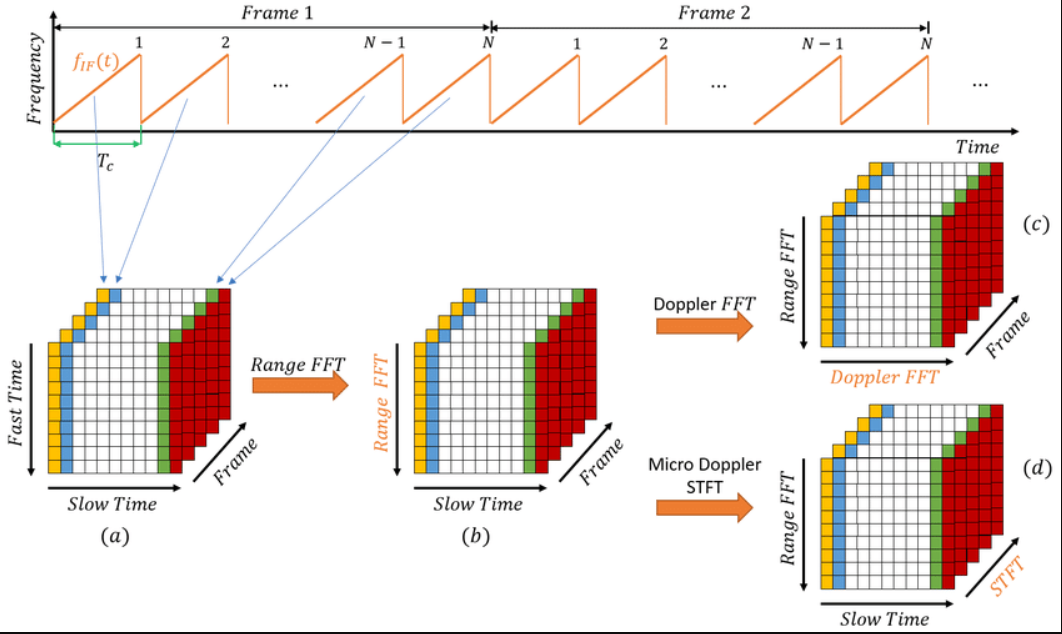

#### Extract Vital Sign and Record it

Select Range 

used_range_low = 50;
used_range_up = 60;

Process FMCW Data



% Set device configuration for presence sensing
f_start = Radar_Parameter.Lower_RF_Frequency_kHz * 1e7; %FMCW chirp start frequency in Hz
f_end   = Radar_Parameter.Upper_RF_Frequency_kHz * 1e7; %FMCW chirp end frequency in Hz

samples_per_chirp  = Radar_Parameter.Samples_per_Chirp;
chirps_per_frame   = Radar_Parameter.Chirps_per_Frame;

zero_padding_factor = 2;

% mat = squeeze(Frame(:,:,2,1));
mat = squeeze(Frame(1,2,:,:));
% mat = transpose(mat);


zero_padded = zeros(size(mat,1),size(mat,2)*2^(zero_padding_factor));
result = zeros(1,200);

hFig = figure('Name','Range Doppler','numbertitle', 'off');
% In this example, show frames till figure is closed.
frame_number = 0;

size_frame = size(Frame);

% mti_history = zeros((self.num_chirps_per_frame, num_samples, num_ant))
mti_history = zeros(Radar_Parameter.Chirps_per_Frame, Radar_Parameter.Samples_per_Chirp, Radar_Parameter.Num_Rx_Antennas);
mti_alpha = 0.8;

n_distance = 2;
n_velocity = 50;
data_vs = [];

countdown = 0;
old_status = 0;
% processed_fmcw = zeros(Radar_Parameter.Chirps_per_Frame,Radar_Parameter.Samples_per_Chirp,size_frame(4));
% processed_fmcw = zeros(Radar_Parameter.Chirps_per_Frame,Radar_Parameter.Samples_per_Chirp,size_frame(1));
processed_fmcw = zeros(Radar_Parameter.Chirps_per_Frame,Radar_Parameter.Samples_per_Chirp,size_frame(1),Radar_Parameter.Num_Rx_Antennas);
filtered_processed_fmcw = zeros(Radar_Parameter.Chirps_per_Frame,Radar_Parameter.Samples_per_Chirp,size_frame(1),Radar_Parameter.Num_Rx_Antennas);
data_vs = zeros(size_frame(1),Radar_Parameter.Num_Rx_Antennas);
data_vs_filt = zeros(size_frame(1),Radar_Parameter.Num_Rx_Antennas);
%##########################################################################
% STEP 6: Continue fetching Radar data and run desired algorithm on it.
%##########################################################################
% while ishandle(hFig)
figure("Name","Frame Surface")
% for loop=1:size_frame(4)
for cur_antenna=1:Radar_Parameter.Num_Rx_Antennas
    for loop=1:size_frame(1)
        range_window = window(@blackmanharris,samples_per_chirp);
        doppler_window = window(@blackmanharris,Radar_Parameter.Chirps_per_Frame);
        % data = Frame(:,:,1,loop);
        data = double(squeeze(Frame(loop,1,:,:)));
        % data = transpose(data);
        data = data - mean(data);

        % data_mti = data - mti_history;
        mti_history(:, :, 1) = data * mti_alpha + mti_history(:, :, 1) * (1 - mti_alpha);

            % Mean removal and windowing of raw data
        avg_windowed = (data - mean(data,2)).*range_window';

        zero_padded(:,1:samples_per_chirp) = avg_windowed;

        % Range FFT
        range_fft = (fft(zero_padded'))/samples_per_chirp; % normalized FFT
        range_fft = 2*range_fft.'; % compensating for the negative half the spectrum
        % remove the redundant negative spectrum since FFT input was real
        fft1d = range_fft(:,1:(size(range_fft,2)/2));

        % fft1d = transpose(fft1d);

        fft1d = fft1d .* doppler_window;

        zero_padded_2(:,1:Radar_Parameter.Chirps_per_Frame) = transpose(fft1d);

        % Range FFT
        range_fft_2 = (fft(zero_padded_2'))/Radar_Parameter.Chirps_per_Frame; % normalized FFT
        range_fft = 2*range_fft_2.'; % compensating for the negative half the spectrum
        % remove the redundant negative spectrum since FFT input was real
        fft2d = range_fft_2(:,1:(size(range_fft_2,2)/2));
        sum_range = fft2d(1,:) + fft2d(2,:) + fft2d(3,:) + fft2d(4,:);
        sum_all = sum(sum(sum_range));
        processed_fmcw(:,:,loop,cur_antenna) = fft2d;
        % data_vs = [data_vs max(max(fft2d))];
        % data_vs = [data_vs max(max(sum_all))];
        
        % Filtered
        [M,I] = max(abs(processed_fmcw(:,:,loop,1)),[],"all","linear");
        [dim1, dim2] = ind2sub(size(processed_fmcw(:,:,loop,1)),I);
    
        [min_M,min_I] = min(abs(processed_fmcw(:,:,loop)),[],"all","linear");
        [min_dim1, min_dim2] = ind2sub(size(processed_fmcw(:,:,loop,1)),min_I);
        size_frame_proc=size(processed_fmcw);
    
        data_treshold = M*0.9;
        new_frame=zeros(size_frame_proc(1),size_frame_proc(2));
        % half_dist_size = round(size_frame(2)/2);
        half_dist_size = size_frame_proc(2);
        for d1_frame=1:size_frame_proc(1)
            for d2_frame=1:half_dist_size
                if(abs(processed_fmcw(d1_frame,d2_frame,loop,1))>data_treshold)
                    % if(
                    new_frame(d1_frame,d2_frame) = abs(processed_fmcw(d1_frame,d2_frame,loop,1));
                end
            end
        end
        % dum_dat = new_frame(120,:)+new_frame(121,:)+new_frame(122,:)+new_frame(123,:)+new_frame(124,:)+new_frame(125,:)+new_frame(126,:)+new_frame(127,:)+new_frame(128,:);
        % data_raw(loop) = max(new_frame)
        % new_frame = new_frame - mean(new_frame);
        % data_raw = max(dum_dat);
        filt_dum_dat = zeros(size_frame_proc(1),1);
        for sel_dat=5:20
            % dum_dat = dum_dat+new_frame(:,sel_dat);
            filt_dum_dat = filt_dum_dat+abs(processed_fmcw(:,sel_dat,loop,cur_antenna));
        end
        data_raw(loop) = sum(filt_dum_dat);

        dum_dat = zeros(size_frame_proc(2),1);
        for sel_dat=used_range_low:used_range_up
            % dum_dat = dum_dat+new_frame(:,sel_dat);
            dum_dat = dum_dat + processed_fmcw(:,sel_dat,loop,cur_antenna);
        end
        % data_raw(loop) = sum(dum_dat);
        data_vs(loop,cur_antenna) = sum(dum_dat);
        % data_vs = [data_vs sum(dum_dat)];


        % fft1d =data_mti .*w';
        % 
        % fft1d = transpose(fft1d);
        % fft1d = times(fft1d,doppler_window);
        % zp2 = np.pad(fft1d, ((0, 0), (0, self.num_chirps_per_frame)), "constant")
        % zp2 = padarray()
        % y_axes = range_arr;
        % % x_axes = 
        % surface(abs(fft2d),"EdgeColor","none")
        % M(loop) = fft2d;
        % view(3)
        % drawnow

    end
end

% cur_antenna=1
% for loop=1:size_frame(1)
%     range_window = window(@blackmanharris,samples_per_chirp);
%     doppler_window = window(@blackmanharris,Radar_Parameter.Chirps_per_Frame);
%     % data = Frame(:,:,1,loop);
%     data = double(squeeze(Frame(loop,1,:,:)));
%     % data = transpose(data);
%     data = data - mean(data);
% 
%     % data_mti = data - mti_history;
%     mti_history(:, :, 1) = data * mti_alpha + mti_history(:, :, 1) * (1 - mti_alpha);
% 
%         % Mean removal and windowing of raw data
%     avg_windowed = (data - mean(data,2)).*range_window';
% 
%     zero_padded(:,1:samples_per_chirp) = avg_windowed;
% 
%     % Range FFT
%     range_fft = (fft(zero_padded'))/samples_per_chirp; % normalized FFT
%     range_fft = 2*range_fft.'; % compensating for the negative half the spectrum
%     % remove the redundant negative spectrum since FFT input was real
%     fft1d = range_fft(:,1:(size(range_fft,2)/2));
% 
%     % fft1d = transpose(fft1d);
% 
%     fft1d = fft1d .* doppler_window;
% 
%     zero_padded_2(:,1:Radar_Parameter.Chirps_per_Frame) = transpose(fft1d);
% 
%     % Range FFT
%     range_fft_2 = (fft(zero_padded_2'))/Radar_Parameter.Chirps_per_Frame; % normalized FFT
%     range_fft = 2*range_fft_2.'; % compensating for the negative half the spectrum
%     % remove the redundant negative spectrum since FFT input was real
%     fft2d = range_fft_2(:,1:(size(range_fft_2,2)/2));
%     sum_range = fft2d(1,:) + fft2d(2,:) + fft2d(3,:) + fft2d(4,:);
%     sum_all = sum(sum(sum_range));
%     processed_fmcw(:,:,loop,cur_antenna) = fft2d;
%     % data_vs = [data_vs max(max(fft2d))];
%     % data_vs = [data_vs max(max(sum_all))];
% 
%     dum_dat = zeros(size_frame(3),1);
%     for sel_dat=used_range_low:used_range_up
%         % dum_dat = dum_dat+new_frame(:,sel_dat);
%         dum_dat = dum_dat + processed_fmcw(:,sel_dat,loop,cur_antenna);
%     end
%     % data_raw(loop) = sum(dum_dat);
%     data_vs = [data_vs sum(dum_dat)];
% 
% 
%     % fft1d =data_mti .*w';
%     % 
%     % fft1d = transpose(fft1d);
%     % fft1d = times(fft1d,doppler_window);
%     % zp2 = np.pad(fft1d, ((0, 0), (0, self.num_chirps_per_frame)), "constant")
%     % zp2 = padarray()
%     % y_axes = range_arr;
%     % % x_axes = 
%     % surface(abs(fft2d),"EdgeColor","none")
%     % M(loop) = fft2d;
%     % view(3)
%     % drawnow
% 
% end



### Visualize Dopper FFT

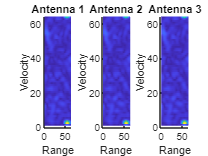

size_frame = size(processed_fmcw);

data_raw = zeros(size_frame(3),1);


figure("Name","Animation ")
for loop=1:size_frame(3)
    [M,I] = max(abs(processed_fmcw(:,:,loop,1)),[],"all","linear");
    [dim1, dim2] = ind2sub(size(processed_fmcw(:,:,loop,1)),I);

    [min_M,min_I] = min(abs(processed_fmcw(:,:,loop)),[],"all","linear");
    [min_dim1, min_dim2] = ind2sub(size(processed_fmcw(:,:,loop,1)),min_I);

    data_treshold = M*0.9;
    new_frame=zeros(size_frame(1),size_frame(2));
    % half_dist_size = round(size_frame(2)/2);
    half_dist_size = size_frame(2);
    for d1_frame=1:size_frame(1)
        for d2_frame=1:half_dist_size
            if(abs(processed_fmcw(d1_frame,d2_frame,loop,1))>data_treshold)
                % if(
                new_frame(d1_frame,d2_frame) = abs(processed_fmcw(d1_frame,d2_frame,loop,1));
            end
        end
    end
    % dum_dat = new_frame(120,:)+new_frame(121,:)+new_frame(122,:)+new_frame(123,:)+new_frame(124,:)+new_frame(125,:)+new_frame(126,:)+new_frame(127,:)+new_frame(128,:);
    % data_raw(loop) = max(new_frame)
    % new_frame = new_frame - mean(new_frame);
    % data_raw = max(dum_dat);
    dum_dat = zeros(size_frame(1),1);
    for sel_dat=5:20
        % dum_dat = dum_dat+new_frame(:,sel_dat);
        dum_dat = dum_dat+abs(processed_fmcw(:,sel_dat,loop,1));
    end
    data_raw(loop) = sum(dum_dat);



    % subplot(1,3,1)
    % surface(abs(processed_fmcw(:,:,loop,1)),"EdgeColor","none")
    % xlabel("Range")
    % ylabel("Velocity")
    % title("Antenna 1")
    % view(2)
    % subplot(1,3,2)
    % surface(abs(processed_fmcw(:,:,loop,2)),"EdgeColor","none")
    % xlabel("Range")
    % ylabel("Velocity")
    % title("Antenna 2")
    % view(2)
    % subplot(1,3,3)
    % surface(abs(processed_fmcw(:,:,loop,3)),"EdgeColor","none")
    % xlabel("Range")
    % ylabel("Velocity")
    % title("Antenna 3")
    % view(2)

    % subplot(1,3,2)
    % surface(new_frame,"EdgeColor","none")
    % view(2)
    % time
    % drawnow
    % pause(0.0001)
end
subplot(1,3,1)
surface(abs(processed_fmcw(:,:,loop,1)),"EdgeColor","none")
xlabel("Range")
ylabel("Velocity")
title("Antenna 1")
view(2)
subplot(1,3,2)
surface(abs(processed_fmcw(:,:,loop,2)),"EdgeColor","none")
xlabel("Range")
ylabel("Velocity")
title("Antenna 2")
view(2)
subplot(1,3,3)
surface(abs(processed_fmcw(:,:,loop,3)),"EdgeColor","none")
xlabel("Range")
ylabel("Velocity")
title("Antenna 3")
view(2)

#### Vital Sign Analysis

% figure("Name","Vital Sign")
t_vs = 1:length(data_vs)

t_vs =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


t_vs = t_vs * Radar_Parameter.Frame_Period_sec;
% data_vs_db = 20 * log10(abs(data_vs))
% plot(t_vs,data_vs_db)
% xlim([20 40]);
% addpath('E:\XSDUX\Heartsound\Heartsound_Analysis');


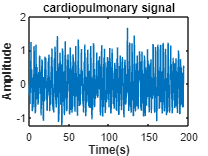

%Get the real and imaginary parts of the signal
data = zeros(length(data_vs));
data_real=zeros(length(data_vs));
data_imag=zeros(length(data_vs));
for k=1:length(data_vs)
    data(k) = data_vs(k);
    data_real(k)=real(data(k));
    data_imag(k)=imag(data(k));
end

%Calculate signal phase
for k=1:length(data_vs)
    signal_phase(k)=atan(data_imag(k)/data_real(k));
end

%Phase unwrapping
for k=2:length(data_vs)
    diff=signal_phase(:,k)-signal_phase(:,k-1);
    if diff>pi/2
        signal_phase(:,(k:end))=signal_phase(:,(k:end))-pi;
    elseif diff<-pi/2
        signal_phase(:,(k:end))=signal_phase(:,(k:end))+pi;
    end
end

%Calculate the phase difference
for k=1:length(data_vs)-1
    % delta_phase(k)=signal_phase(k+1)-signal_phase(k);
    phaseUsedComputation(k)=signal_phase(k+1)-signal_phase(k);
end

%Original signal bandpass filtering
% thresh=0.000000000001;
% for k=1:length(data_vs)-3
%     phaseUsedComputation(k)=filter_RemoveImpulseNoise(delta_phase(k),delta_phase(k+1),delta_phase(k+2),thresh);
% end
% index=1:1:length(data_vs)-1;
% index=1:1:length(phaseUsedComputation);
% index=index*Tf;

N=1024; 
Tf=Radar_Parameter.Frame_Period_sec;       %frame period
%Original signal bandpass filtering
filter_delta_phase=filter(bpf_vitalsign,phaseUsedComputation);


vital_sign=filter_delta_phase;
index = t_vs;
index = index(1:length(index)-1);
%Original Signal Time Domain Plot
figure("Name","Vital Sign");
plot(index,vital_sign);
xlabel('Time(s)','FontWeight','bold');
ylabel('Amplitude','FontWeight','bold');
title('cardiopulmonary signal','FontWeight','bold');

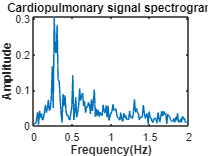


%do fft on the original signal
vital_sign_fft=fft(vital_sign,N);

%Convert double sideband signal to single sideband
freq=(0:1:N/2)/Tf/N;  %The vital sign signal sampling rate is the number of frames
P2 = abs(vital_sign_fft/(N-1));
P1 = P2(1:N/2+1);   %Select the first half at this time, because after fft is a symmetrical bilateral spectrum
P1(2:end-1) = 2*P1(2:end-1);

%Original signal frequency domain plot
figure("Name","Original Signal Frequency");
plot(freq,P1);
xlim([0,2]);
xlabel('Frequency(Hz)','FontWeight','bold');
ylabel('Amplitude','FontWeight','bold');
title('Cardiopulmonary signal spectrogram','FontWeight','bold');

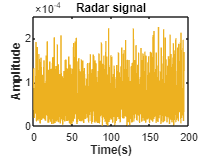


%% Show Pre VITAL SIGN Process
figure("Name","Non VITAL BAND");
plot(t_vs,abs(data_vs));
xlabel('Time(s)','FontWeight','bold');
ylabel('Amplitude','FontWeight','bold');
title('Radar signal','FontWeight','bold');

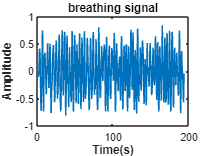


% %Breathing signal bandpass filtering
% filter_delta_phase_breathe=filter(bpf_breathe,data_vs);
filter_delta_phase_breathe=filter(bpf_breathe,phaseUsedComputation);

breathe=filter_delta_phase_breathe;

%Time Domain Diagram of Respiration Signal
figure("Name","Breathing Data");
plot(index,breathe);
xlabel('Time(s)','FontWeight','bold');
ylabel('Amplitude','FontWeight','bold');
title('breathing signal','FontWeight','bold');

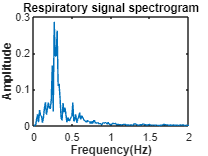


%Do fft on respiration signal
breathe_fft=fft(breathe,N);

%Convert double sideband signal to single sideband
P2_breathe = abs(breathe_fft/(N-1));
P1_breathe = P2_breathe(1:N/2+1);   %Select the first half at this time, because after fft is a symmetrical bilateral spectrum
P1_breathe(2:end-1) = 2*P1_breathe(2:end-1);

%Respiratory signal frequency domain diagram
figure("Name","Respiratory signal spectrogram");
plot(freq,P1_breathe);
xlim([0,2]);
xlabel('Frequency(Hz)','FontWeight','bold');
ylabel('Amplitude','FontWeight','bold');
title('Respiratory signal spectrogram','FontWeight','bold');

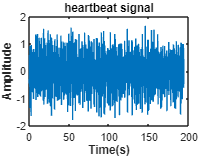



%Heartbeat signal bandpass filtering
filter_delta_phase_heart=filter(bpf_heart,phaseUsedComputation);

heart=filter_delta_phase_heart;

%Heartbeat signal time domain diagram
% figure(5);
figure("Name","Selected Heart Signal x Time Domain");
plot(index,heart);
% xlim([0 20])
xlabel('Time(s)','FontWeight','bold');
ylabel('Amplitude','FontWeight','bold ');
title('heartbeat signal','FontWeight','bold');

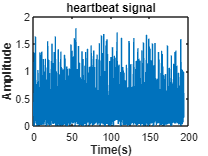


% figure(6);
figure("Name","Selected Heart Signal ABS x Time Domain");
plot(index,abs(heart));
% xlim([0 20])
xlabel('Time(s)','FontWeight','bold');
ylabel('Amplitude','FontWeight','bold ');
title('heartbeat signal','FontWeight','bold');


% Do fft on the heartbeat signal
heart_fft=fft(heart,N);
% 
% %Convert double sideband signal to single sideband
% P2_heart = abs(heart_fft/(N-1));
% P1_heart = P2_heart(1:N/2+1);   %Select the first half at this time, because after fft is a symmetrical bilateral spectrum
% P1_heart(2:end-1) = 2*P1_heart(2:end-1);
% 
% %Heartbeat Harmonic Detection
% [heart_peaks,heart_peaksnum]=findpeaks_1(P1_heart,0.9,2,N,Tf);%0.9Hz-2Hz
% [heart_harmonic_peaks,heart_harmonic_peaksnum]=findpeaks_1(P1_heart,1.8,4,N,Tf);%1.8Hz-4Hz
% heart_peaks=heart_peaks/N/Tf;
% heart_harmonic_peaks=heart_harmonic_peaks/N/Tf;
% [heart_peaks_row,heart_peaks_column]=size(heart_peaks);
% [heart_harmonic_peaks_row,heart_harmonic_peaks_column]=size(heart_harmonic_peaks);
% for i=1:heart_peaks_column
%     if max(P1_heart)-P1_heart(round(heart_peaks(i)*N*Tf)+1)<0.3 % When the difference between the two peaks is within a certain range, the signal that finds the harmonic is expanded
%         for j=1:heart_harmonic_peaks_column
%             if heart_harmonic_peaks(j)/heart_peaks(i)==2
%                 P1_heart(round(heart_peaks(i)*N*Tf)+1)=2*P1_heart(round(heart_peaks(i)*N*Tf)+1);
%             end
%         end
%     end
% end
% 
% %Heartbeat signal frequency domain diagram
% figure("Name","Heartbeat signal frequency domain diagram");
% plot(freq,P1_heart);
% xlim([0,4]);
% xlabel('Frequency(Hz)','FontWeight','bold');
% ylabel('Amplitude','FontWeight','bold');
% title('Spectrum diagram of heartbeat signal','FontWeight','bold');
% 
% %% EEMD Radar Processing 
% % figure("Name","EEMD Data")
% fs = index(1);
% % [imfEnst,imft] = eemd2(transpose(heart),fs,5,100,5,0);
% % [imfEnst,imft] = eemd2(transpose(vital_sign),fs,5,100,5,0);
% [imfEnst,imft] = eemd2(transpose(abs(phaseUsedComputation)),fs,5,100,5,0);
% 
% %% Get All IMF
% figure("Name","EEMD Signal")
% len_imf = length(imft(:,1));
% for c = 1:len_imf
%     subplot(len_imf,1,c);
%     if(c==2)
%         plot(index,imft(c,:)) 
%     end
%     plot(index,imft(c,:)) 
%     s_title = "IMF " + num2str(c);
%     title(s_title)
% end
% 
% %% Get Specific IMF
% figure("Name","EEMD 2 Signal")
% plot(index,imft(3,:)*3) 
% 
% % figure,
% %% Get All imf Ensemble IMF
% figure("Name","EEMD 3 Signal")
% len_imfe = length(imfEnst(:,1));
% for c = 1:len_imfe
%     subplot(len_imfe,1,c);
%     plot(index,imfEnst(c,:)) 
%     s_title = "IMFe " + num2str(c);
%     title(s_title)
%     % xlim([30 50])
% 
% end
% 
% %% Try Mix Some Signal
% mixed_eemd = (imft(3,:)+imfEnst(3,:))*3;
% figure("Name","EEMD MIX Signal")
% plot(index,mixed_eemd) 
% % figure,
% 
% figure("Name","HEART x RADAR")
% subplot(2,1,1)
% plot(index,abs(heart));
% xlim([0 5])
% subplot(2,1,2)
% plot(bio_t_fe,ecg_fe);
% xlim([0 5])
% 
% figure("Name","HEART x RADAR 2")
% % subplot(2,1,1)
% plot(index,heart,bio_t_fe,pcg_fe);
% xlim([0 10])
% % subplot(2,1,2)
% % plot(bio_t_fe,pcg_fe);
% % xlim([0 20])
% 
% 
% % Do fft on the heartbeat signal
% pcg_fft=fft(pcg_fe,N);
% 
% %Convert double sideband signal to single sideband
% P2_pcg = abs(pcg_fft/(N-1));
% P1_pcg = P2_pcg(1:N/2+1);   %Select the first half at this time, because after fft is a symmetrical bilateral spectrum
% P2_pcg(2:end-1) = 2*P2_pcg(2:end-1);
% 
% % xlabel('Time(s)','FontWeight','bold');
% % ylabel('Amplitude','FontWeight','bold ');
% % title('heartbeat signal','FontWeight','bold');
% 
% % %Heartbeat Harmonic Detection
% % [heart_peaks,heart_peaksnum]=findpeaks_1(P1_heart,0.9,2,N,Tf);%0.9Hz-2Hz
% % [heart_harmonic_peaks,heart_harmonic_peaksnum]=findpeaks_1(P1_heart,1.8,4,N,Tf);%1.8Hz-4Hz
% % heart_peaks=heart_peaks/N/Tf;
% % heart_harmonic_peaks=heart_harmonic_peaks/N/Tf;
% % [heart_peaks_row,heart_peaks_column]=size(heart_peaks);
% % [heart_harmonic_peaks_row,heart_harmonic_peaks_column]=size(heart_harmonic_peaks);
% % for i=1:heart_peaks_column
% %     if max(P1_heart)-P1_heart(round(heart_peaks(i)*N*Tf)+1)<0.3 % When the difference between the two peaks is within a certain range, the signal that finds the harmonic is expanded
% %         for j=1:heart_harmonic_peaks_column
% %             if heart_harmonic_peaks(j)/heart_peaks(i)==2
% %                 P1_heart(round(heart_peaks(i)*N*Tf)+1)=2*P1_heart(round(heart_peaks(i)*N*Tf)+1);
% %             end
% %         end
% %     end
% % end
% 
% Tf2 = bio_t_fe(2);
% freq2=(0:1:N/2)/Tf2/N;  %The vital sign signal sampling rate is the number of frames
% 
% %Heartbeat signal frequency domain diagram
% figure("Name","PCG frequency domain diagram");
% plot(freq2,transpose(P1_pcg));
% % xlim([0,10]);
% xlabel('Frequency(Hz)','FontWeight','bold');
% ylabel('Amplitude','FontWeight','bold');
% title('Spectrum diagram of heartbeat signal','FontWeight','bold');
% 
% global radar_t;
% global radar_hr_processed;
% global radar_rr_processed;
% radar_t             = index;
% radar_rr_processed  = imft(2,:);
% % radar_hr_processed = ;
% % radar_rr_processed = ;


Visualize VMD

%VMD parameter settings
alpha = 5000;      % moderate bandwidth constraint
tau = 0;            % noise-tolerance (no strict fidelity enforcement)0
K = 3;              % modes
DC = 0;             % no DC part imposed
init = 1;           % initialize omegas uniformly
tol = 1e-6;

%VMD
[u, u_hat, omega] = VMD(vital_sign, alpha, tau, K, DC, init, tol);

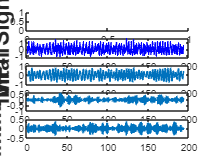


%% Plot VMD Decomposition
figure
subplot(length(u(:,1))+2,1,1);
% indexnya = 1:(length(radar_raw_real)/2);
% indexnya = indexnya * (Tc/numADCSamples);
% plot(index, radar_raw_real(1:length(radar_raw_real)/2))
% ylabel('Raw','fontweight','bold','fontsize',18)
subplot(length(u(:,1))+2,1,2);
plot(index,vital_sign,'LineWidth',1,'color','b')
ylabel('Vital Sign','fontweight','bold','fontsize',18)
for ii=1:length(u(:,1))
    subplot(length(u(:,1))+2,1,ii+2);
    title_imf = append('IMF-',int2str(ii));    
    plot(index,u(ii,:));
    if(ii==length(u(:,1)))
        xlabel('Time(s)')
        xlabel('Time (s)','fontweight','bold','fontsize',20)
    end
    ylabel(title_imf,'fontweight','bold','fontsize',18)
   
end